# Discrete (energy) conservation

clear, close all, clc
set_demo_defaults()

## Numerical solution for continental geotherm

Assuming standard coefficients

qs = 65e-3;   % ave. surface heat flow [W/m^2]
rho = 2700;   % ave. crustal density [kg/m^3]
H0 = 9.6e-10; % heat production near surface [W/kg]
h = 35e3;     % ave. depth of crust [m]
kappa = 3.35; % thermal conductivity [W/(m K)]

Analytic solutions

q = @(z,qm) -qm-rho*H0*hr*(exp(-z/hr)-exp(-h/hr));
T = @(z,T0,qm) T0 + (qm/kappa-rho*H0*hr/kappa*exp(-h/hr))*z + rho*H0*hr^2/kappa*(1-exp(-z/hr));
zplot = linspace(0,h,100);

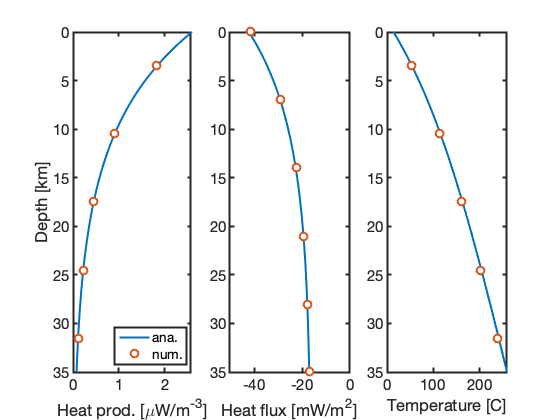

T0 = 14;
hr = 10e3;
qm = 17e-3; 
q = @(z) -qm-rho*H0*hr*(exp(-z/hr)-exp(-h/hr));
T = @(z) T0 + (qm/kappa-rho*H0*hr/kappa*exp(-h/hr))*z + rho*H0*hr^2/kappa*(1-exp(-z/hr));
zplot = linspace(0,h,100);
figure(1)
subplot 131
plot(rho*H0*exp(-zplot/hr)*1e6,zplot/1e3),hold on
set(gca, 'YDir','reverse')
xlabel('Heat prod. [\muW/m^{-3}]')
ylabel('Depth [km]')

subplot 132
plot(q(zplot)*1e3,zplot/1e3), hold on
set(gca, 'YDir','reverse')
xlabel('Heat flux [mW/m^2]')
xlim([-50 0])
% ylabel('Depth [km]')

subplot 133
plot(T(zplot),zplot/1e3), hold on

set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
% ylabel('Depth [km]')

% 0) Note we have already defined all physical constants above
% 1) Define the domain and create the grid
Grid.xmin = 0; Grid.xmax = h; Grid.Nx = 5; % Note: here x is the depth
Grid = build_grid(Grid);
% 2) Build operators and r.h.s.
[D,G,~,I,M] = build_ops(Grid);
L = -D*kappa*G;
fs = rho*H0*exp(-Grid.xc/hr);
% 3) Define location and value of BC's
BC.dof_dir   = Grid.dof_xmin;   % Dirichlet BC at x = 0
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g         = T(Grid.dx/2);    % Using analytic solution to set BC in cell center
BC.dof_neu   = Grid.dof_xmax;   % Neuman BC at x = h
BC.dof_f_neu = Grid.dof_f_xmax;
BC.qb        = qm;             % Mantle heat flow (positve, i.e. into the crust)
[B,N,fn] = build_bnd(BC,Grid,I);
% 4) Solve BVP and compute the heat flux
Tnum = solve_lbvp(L,fs+fn,B,BC.g,N);
qnum = comp_flux(D,kappa,G,Tnum,fs,Grid,BC);

figure(1)
subplot 131
plot(fs*1e6,Grid.xc/1e3,'o','markerfacecolor','w','markersize',8)
legend('ana.','num.','location','southeast')
subplot 132
plot(qnum*1e3,Grid.xf/1e3,'o','markerfacecolor','w','markersize',8)

subplot 133
plot(Tnum,Grid.xc/1e3,'o','markerfacecolor','w','markersize',8)

## How good is the predicted surface heat flow

How big is the error in the surface heat flow in percent?

err = abs(qnum(Grid.dof_xmin)-q(0))/abs(q(0))*100

err = 1.2008

This error is small but not round off, how does it change with grid refinement?

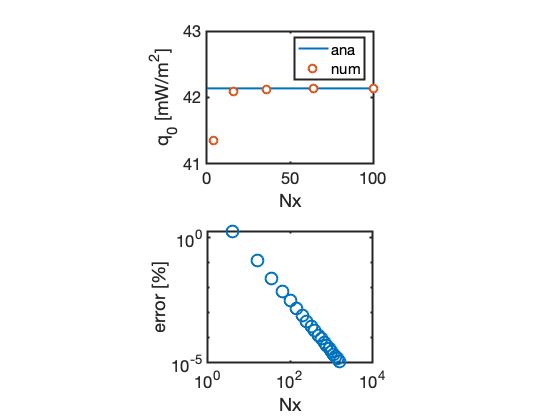

Nx_vec = [2:2:40].^2;
q0_vec = zeros(length(Nx_vec),1);
err_vec = q0_vec;
for i = 1:length(Nx_vec)
    q0_vec(i) = comp_surface_heat_flow(Nx_vec(i),rho,H0,h,hr,kappa,qm,T);
    err_vec(i) = abs((q0_vec(i)-q(0))/q(0)*100);
end
figure
subplot 211
plot([0,1600],abs(q(0))*[1 1]*1e3,'-'), hold on
plot(Nx_vec,abs(q0_vec)*1e3,'o','markerfacecolor','w','markersize',8)
pbaspect([1 .8 1])
xlim([0 100]), ylim([41 43])
xlabel 'Nx', ylabel 'q_0 [mW/m^2]'
legend('ana','num')
subplot 212
loglog(Nx_vec,err_vec,'o')
pbaspect([1 .8 1])
xlim([1e0 1e4])
xlabel 'Nx', ylabel 'error [%]'

Why is the error not zero? 

## Conservative treatment of source term

In our discretization the flux through the boundaries exactly reflects the the heat added by the source term. (That is the meaning of discrete conservation.) Hence, the observation that the computed surface heat flow is less than it should be indicates that our r.h.s. source term does not add the correct amount of heat.

This is because the value of the source term at the call center does not represent the average of the source term over the cell. The definite integral of the source term of the the finite interval [a, b] is given by


$$\langle f_{s,i}\rangle =\frac{1}{\Delta x}\int_{x_{f,i}}^{x_{f,i+1}} \rho H_0e^{-z/h_r}\mathrm{d}z = \frac{\rho H_0 h_r}{\Delta x}\left(e^{-x_{f,i}/h_r}-e^{-x_{f,i+1}/h_r}\right)$$


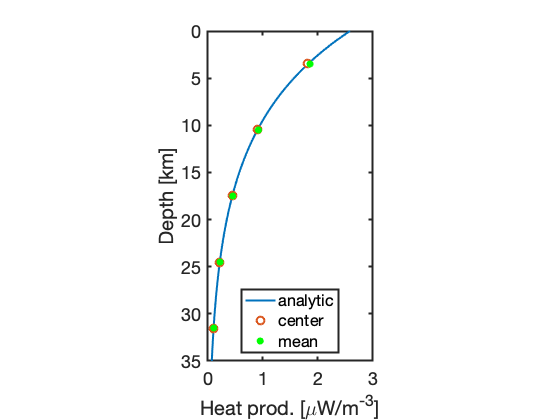

fs_cen = rho*H0*exp(-Grid.xc/hr);
fs_ave = rho*H0*hr*(exp(-Grid.xf(1:Grid.Nx)/hr)-exp(-Grid.xf(2:Grid.Nfx)/hr))/Grid.dx;

figure
plot(rho*H0*exp(-zplot/hr)*1e6,zplot/1e3),hold on
plot(fs*1e6,Grid.xc/1e3,'o','markerfacecolor','w','markersize',8)
plot(fs_ave*1e6,Grid.xc/1e3,'g.','markersize',18)
legend('analytic','center','mean','location','south')
set(gca, 'YDir','reverse')
xlabel('Heat prod. [\muW/m^{-3}]')
ylabel('Depth [km]')
xlim([0 3])
pbaspect([.5 1 1])

Convergence study shows that this leads to the correct surface flux, irrespective of the grid! 

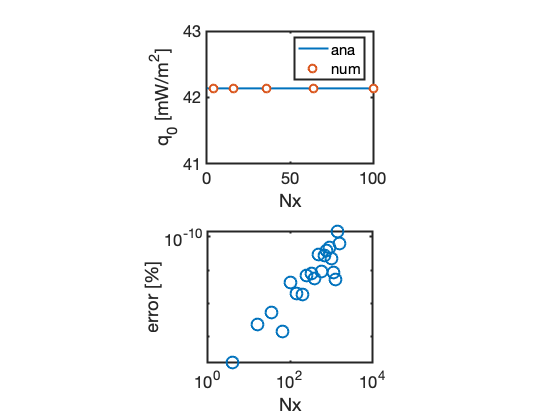

Nx_vec = [2:2:40].^2;
q0_vec = zeros(length(Nx_vec),1);
err_vec = q0_vec;
for i = 1:length(Nx_vec)
    q0_vec(i) = comp_surface_heat_flow_conservative(Nx_vec(i),rho,H0,h,hr,kappa,qm,T);
    err_vec(i) = abs((q0_vec(i)-q(0))/q(0)*100);
end
figure
subplot 211
plot([0,1600],abs(q(0))*[1 1]*1e3,'-'), hold on
plot(Nx_vec,abs(q0_vec)*1e3,'o','markerfacecolor','w','markersize',8)
pbaspect([1 .8 1])
xlim([0 100]), ylim([41 43])
xlabel 'Nx', ylabel 'q_0 [mW/m^2]'
legend('ana','num')
subplot 212
loglog(Nx_vec,err_vec,'o')
pbaspect([1 .8 1])
xlim([1e0 1e4])
xlabel 'Nx', ylabel 'error [%]'

# Auxillary functions

function [q0] = comp_surface_heat_flow(Nx,rho,H0,h,hr,kappa,qm,T)
% 1) Define the domain and create the grid
Grid.xmin = 0; Grid.xmax = h; Grid.Nx = Nx; % Note: here x is the depth
Grid = build_grid(Grid);
% 2) Build operators and r.h.s.
[D,G,~,I,M] = build_ops(Grid);
L = -D*kappa*G;
fs = rho*H0*exp(-Grid.xc/hr);
% 3) Define location and value of BC's
BC.dof_dir   = Grid.dof_xmin;   % Dirichlet BC at x = 0
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g         = T(Grid.dx/2);    % Using analytic solution to set BC in cell center
BC.dof_neu   = Grid.dof_xmax;   % Neuman BC at x = h
BC.dof_f_neu = Grid.dof_f_xmax;
BC.qb        = qm;             % Mantle heat flow (positve, i.e. into the crust)
[B,N,fn] = build_bnd(BC,Grid,I);
% 4) Solve BVP and compute the heat flux
Tnum = solve_lbvp(L,fs+fn,B,BC.g,N);
qnum = comp_flux(D,kappa,G,Tnum,fs,Grid,BC);
q0 = qnum(1);
end

function [q0] = comp_surface_heat_flow_conservative(Nx,rho,H0,h,hr,kappa,qm,T)
% 1) Define the domain and create the grid
Grid.xmin = 0; Grid.xmax = h; Grid.Nx = Nx; % Note: here x is the depth
Grid = build_grid(Grid);
% 2) Build operators and r.h.s.
[D,G,~,I,M] = build_ops(Grid);
L = -D*kappa*G;
fs = rho*H0*hr*(exp(-Grid.xf(1:Grid.Nx)/hr)-exp(-Grid.xf(2:Grid.Nfx)/hr))/Grid.dx;
% 3) Define location and value of BC's
BC.dof_dir   = Grid.dof_xmin;   % Dirichlet BC at x = 0
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g         = T(Grid.dx/2);    % Using analytic solution to set BC in cell center
BC.dof_neu   = Grid.dof_xmax;   % Neuman BC at x = h
BC.dof_f_neu = Grid.dof_f_xmax;
BC.qb        = qm;             % Mantle heat flow (positve, i.e. into the crust)
[B,N,fn] = build_bnd(BC,Grid,I);
% 4) Solve BVP and compute the heat flux
Tnum = solve_lbvp(L,fs+fn,B,BC.g,N);
qnum = comp_flux(D,kappa,G,Tnum,fs,Grid,BC);
q0 = qnum(1);
end